**Taller Integrador: Diseño e Implementación Digital de Controladores PID **

Integrantes:

Daniel Felipe Sarmiento Pilonieta - 2202797

Monica Cristina Peña Rincon - 2205125

Fabian Andres Amador Ballesteros - 2204215

**PROBLEMA 1**

- ***Punto 1: ****Identificación de parámetros para sintonización*

% Planta
clear
clc
close all

s=tf('s');
G=6/((1.5*s+1)*(0.7*s+1)*(0.3*s+1));

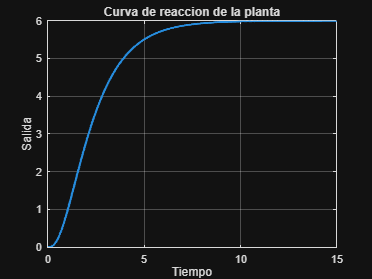

% Curva de reaccion del proceso

dt=0.01;
t=0:dt:15;

u=ones(size(t));% entrada escalon
y=lsim(G,u,t); % salida del sistema

figure
plot(t,y,'LineWidth',2)
grid on
title('Curva de reaccion de la planta')
xlabel('Tiempo')
ylabel('Salida')

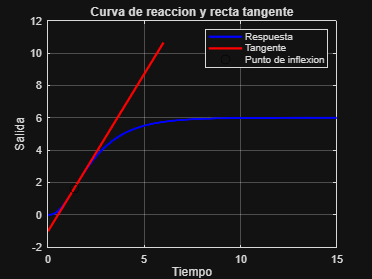

%% Punto de inflexion

dy=diff(y)/dt; % derivada de la respuesta

[m,p]=max(dy);% pendiente maxima

yp=y(p); %valor de la salida en ese punto
tp=t(p); %tiempo del punto de inflexión

%Dibujar la recta tengente

tm=0:6;
ym=m*(tm-tp)+yp;
figure
plot(t,y,'b','LineWidth',2)
hold on
plot(tm,ym,'r','LineWidth',2)
plot(tp,yp,'ko','MarkerSize',8)
grid on
title('Curva de reaccion y recta tangente')
xlabel('Tiempo')
ylabel('Salida')
legend('Respuesta','Tangente','Punto de inflexion')

%% Modelo Identificado del Sistema
K = 6;    %Ganancia del Sistema

%valores a determinar desde la gráfica
% Para contrastar medir t1 y t2 correspondiente al 28,3% del valor final y
% 63,2% del valor final 
% Busco para t1 respuesta en 6*(0.283)=1.698
% Busco para t2 respuesta en 6*(0.632)=3.792
t1= 1.37;
t2= 2.65;

Texp=1.5*(t2-t1);
Lexp=t2-Texp;
tau = Texp;
theta = Lexp;

disp('Parametros del modelo FOPDT:')

Parametros del modelo FOPDT:


fprintf('K = %.3f\n',K)

K = 6.000


fprintf('T = %.3f\n',Texp)

T = 1.920


fprintf('L = %.3f\n',Lexp)

L = 0.730


fprintf('tau = %.3f\n',tau)

tau = 1.920


fprintf('theta = %.3f\n',theta)

theta = 0.730


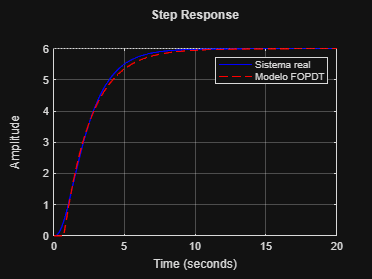


%Modelo equivalente tipo FOPDT
Gm=tf([K],[Texp 1]);
Gm.iodelay=Lexp;

figure
step(G,'b',Gm,'r--',20)
legend('Sistema real','Modelo FOPDT')
grid on

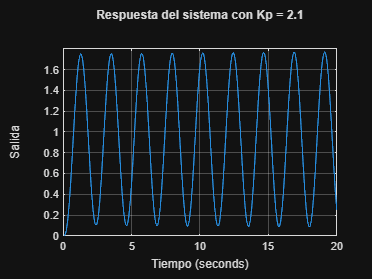

%% Metodo de oscilacion sostenida (Ku y Pu)

Kp1 = 2.1; % <-- modificar manualmente este valor hasta observar oscilacion

C = pid(Kp1); % controlador proporcional

T = feedback(C*G,1); % sistema en lazo cerrado con realimentacion unitaria

figure
step(T,20) 
grid on
title(['Respuesta del sistema con Kp = ',num2str(Kp1)])
xlabel('Tiempo')
ylabel('Salida')


% Parametros obtenidos por oscilacion sostenida
Ku=Kp1;
% Observando la grafica para Pu que seria el periodo t2-t1
Pu = 5.72 - 3.55;
fprintf('Ku = %.3f\n',Ku)

Ku = 2.100


fprintf('Pu = %.3f\n',Pu)

Pu = 2.170


- **Punto 2: **Diseño continuo y comparación

**Ziegler–Nichols**

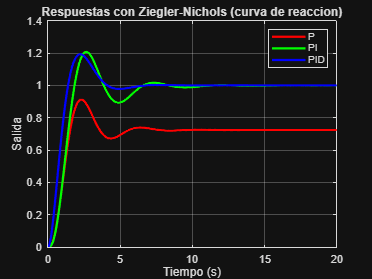

%Sintonizacion por metodo Ziegler-Nichols (curva de reaccion)

%Controlador P
Kp = Texp/(K*Lexp);  
Ki = 0;              
Kd = 0;              

Cp1 = pid(Kp,Ki,Kd); 

Glc = feedback(series(Cp1,G),1); % sistema en lazo cerrado

[yp,tp] = step(Glc,20); 

%% Controlador PI

Kp = 0.9*Texp/(K*Lexp); 
Ti = Lexp/0.3;          
Ki = Kp/Ti;             
Kd = 0;                 

Cpi1 = pid(Kp,Ki,Kd);  

Glc = feedback(series(Cpi1,G),1); 

[ypi,tpi] = step(Glc,20);

%% Controlador PID

Kp = 1.2*Texp/(K*Lexp); 
Ti = 2*Lexp;            
Td = 0.5*Lexp;          

Ki = Kp/Ti;             
Kd = Kp*Td;             

Cpid1 = pid(Kp,Ki,Kd);  

Glc = feedback(series(Cpid1,G),1);

[ypid,tpid] = step(Glc,20);

%% Comparacion de respuestas

figure(3)

plot(tp,yp,'r','LineWidth',2)
hold on
plot(tpi,ypi,'g','LineWidth',2)
plot(tpid,ypid,'b','LineWidth',2)

legend('P','PI','PID')

grid on
title('Respuestas con Ziegler-Nichols (curva de reaccion)')
xlabel('Tiempo (s)')
ylabel('Salida')

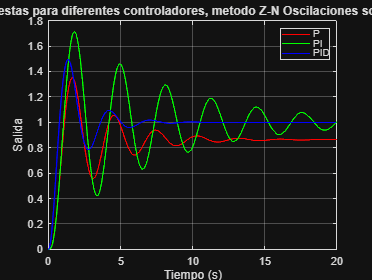

% Sintonizacion por metodo Ziegler-Nichols Oscilaciones sostenidas


% Controlador P
Kp=0.5*Ku; 
Kd=0;      
Ki=0;      

Cp2=pid(Kp,Ki,Kd); 
Glc=feedback(series(Cp2,G),1); % Lazo cerrado
[yp2,tp2]=step(Glc,20); % Respuesta al escalon

% Controlador PI
Kp=0.45*Ku; 
Kd=0;       
Ti=Pu/1.2;  
Ki=Kp/Ti;   

Cpi2=pid(Kp,Ki,Kd); 
Glc=feedback(series(Cpi2,G),1); 
[ypi2,tpi2]=step(Glc,20); 

% Controlador PID
Kp=0.6*Ku; 
Td=Pu/8;   
Kd=Kp*Td;  
Ti=Pu/2;   
Ki=Kp/Ti;  

Cpid2=pid(Kp,Ki,Kd); 
Glc=feedback(series(Cpid2,G),1); 
[ypid2,tpid2]=step(Glc,20);

figure(4)
plot(tp2,yp2,'r',tpi2,ypi2,'g',tpid2,ypid2,'b')
legend('P','PI','PID')
grid on
title('Respuestas para diferentes controladores, metodo Z-N Oscilaciones sostenidas')
xlabel('Tiempo (s)')
ylabel('Salida')

**CHR para 20 % de sobreimpulso**

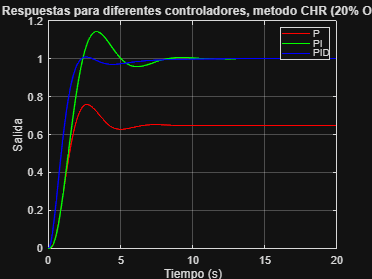

%% Metodo 3 CHR

% Sintonia CHR para respuesta rapida con 20% de sobreimpulso
% usando los parametros del modelo FOPDT

% Control P - CHR
kc7 = (0.7*tau) / (K*theta);

% Ganancias
Kp7 = kc7;
Ki7 = 0;
Kd7 = 0;

Cp3 = pid(Kp7,Ki7,Kd7);
Glc = feedback(series(Cp3,G),1);
[yp3,tp3] = step(Glc,20);

% Control PI - CHR
kc8 = (0.6*tau) / (K*theta);
ti8 = tau;

% Ganancias
Kp8 = kc8;
Ki8 = kc8/ti8;
Kd8 = 0;

Cpi3 = pid(Kp8,Ki8,Kd8);
Glc = feedback(series(Cpi3,G),1);
[ypi3,tpi3] = step(Glc,20);

% Control PID - CHR
kc9 = (0.95*tau) / (K*theta);
ti9 = 1.357*tau;
td9 = 0.473*theta;

% Ganancias
Kp9 = kc9;
Ki9 = kc9/ti9;
Kd9 = kc9*td9;

Cpid3 = pid(Kp9,Ki9,Kd9);
Glc = feedback(series(Cpid3,G),1);
[ypid3,tpid3] = step(Glc,20);

figure(5)
plot(tp3,yp3,'r',tpi3,ypi3,'g',tpid3,ypid3,'b')
legend('P','PI','PID')
grid on
title('Respuestas para diferentes controladores, metodo CHR (20% OS)')
xlabel('Tiempo (s)')
ylabel('Salida')

- Comparación en lazo cerrado continuo

%  METODO ZN CURVA DE REACCION 

% calculo del error
e1 = 1 - ypid;   % error entre referencia (1) y salida

% indices de desempeño
IAE1 = trapz(tpid,abs(e1));      % Integral del error absoluto
ITSE1 = trapz(tpid,tpid.*(e1.^2)); % Integral del tiempo por error^2

% informacion de la respuesta
info1 = stepinfo(ypid,tpid);

Mp1 = info1.Overshoot;      % sobreimpulso (%)
ts1 = info1.SettlingTime;   % tiempo de establecimiento


%  METODO ZN OSCILACION SOSTENIDA 

e2 = 1 - ypid2;

IAE2 = trapz(tpid2,abs(e2));
ITSE2 = trapz(tpid2,tpid2.*(e2.^2));

info2 = stepinfo(ypid2,tpid2);

Mp2 = info2.Overshoot;
ts2 = info2.SettlingTime;


% METODO CHR 

e3 = 1 - ypid3;

IAE3 = trapz(tpid3,abs(e3));
ITSE3 = trapz(tpid3,tpid3.*(e3.^2));

info3 = stepinfo(ypid3,tpid3);

Mp3 = info3.Overshoot;
ts3 = info3.SettlingTime;


Metodo = ["ZN Reaccion";"ZN Oscilacion";"CHR"];

Mp = [Mp1; Mp2; Mp3];
ts = [ts1; ts2; ts3];
IAE = [IAE1; IAE2; IAE3];
ITSE = [ITSE1; ITSE2; ITSE3];

Tabla_resultados = table(Metodo,Mp,ts,IAE,ITSE)

Tabla_resultados = 3×5 table
        Metodo           Mp         ts       IAE       ITSE  
    _______________    _______    ______    ______    _______

    "ZN Reaccion"       19.278    5.2208    1.0668    0.28778
    "ZN Oscilacion"     49.408    6.1375    1.2295    0.43401
    "CHR"              0.86392    5.7214    1.0511    0.29083


**Análisis en frecuencia del lazo abierto**

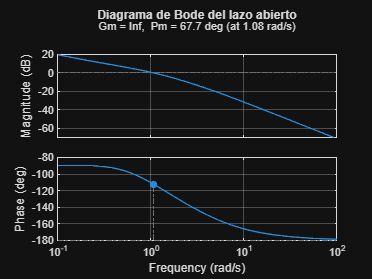

%% ANALISIS EN FRECUENCIA DEL LAZO ABIERTO

% Lazo abierto
L = Cpid3*G;

figure
margin(L)      % Bode con margenes
grid on
title('Diagrama de Bode del lazo abierto')


[Gm,Pm,Wcg,Wcp] = margin(L);

fprintf('Margen de ganancia = %.2f dB\n',20*log10(Gm))

Margen de ganancia = Inf dB


fprintf('Margen de fase = %.2f grados\n',Pm)

Margen de fase = 67.74 grados


fprintf('Frecuencia cruce de ganancia = %.2f rad/s\n',Wcg)

Frecuencia cruce de ganancia = Inf rad/s


- **Punto 3.** Implementación digital, saturación, anti-windup y derivada

%% PUNTO 3.1 DISCRETIZACION DEL PID (METODO TUSTIN)

Ts = 0.05; % periodo de muestreo especificado en el taller

% Crear el controlador PID continuo obtenido con CHR
Cpid_cont = pid(Kp9,Ki9,Kd9);

% Convertir el PID continuo a PID discreto usando Tustin
Cpid_d = c2d(Cpid_cont,Ts,'tustin');

disp('Controlador PID discreto obtenido:')

Controlador PID discreto obtenido:


Cpid_d


Cpid_d =
 
            Ts*(z+1)        2*(z-1) 
  Kp + Ki * -------- + Kd * --------
            2*(z-1)         Ts*(z+1)

  with Kp = 0.416, Ki = 0.16, Kd = 0.144, Ts = 0.05
 
Sample time: 0.05 seconds
Discrete-time PID controller in parallel form.


%% Preparacion para simulaciones digitales

Tsim = 20; % tiempo total de simulacion
td = 0:Ts:Tsim; % vector de tiempo discreto
N = length(td); % numero de muestras

r = ones(1,N); % referencia (escalon unitario)

% Convertir la planta a espacio de estados
[A,B,C,D] = ssdata(ss(G));

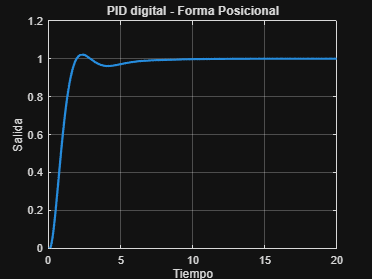

%% 3.2.1 PID DIGITAL - FORMA POSICIONAL

y_pos = zeros(1,N); % salida del sistema
u_pos = zeros(1,N); % señal de control
e_pos = zeros(1,N); % error

x = zeros(size(A,1),1); % estados iniciales de la planta

for k = 2:N
    
    % calcular error
    e_pos(k) = r(k) - y_pos(k-1);
    
    % termino proporcional
    P = Kp9 * e_pos(k);
    
    % termino integral (suma acumulada del error)
    I = Ki9 * Ts * sum(e_pos(1:k));
    
    % termino derivativo
    D = Kd9 * (e_pos(k) - e_pos(k-1)) / Ts;
    
    % señal de control total
    u_pos(k) = P + I + D;
    
    % actualizar dinamica de la planta
    x = x + Ts*(A*x + B*u_pos(k));
    
    % salida del sistema
    y_pos(k) = C*x;
    
end

figure
plot(td,y_pos,'LineWidth',2)
grid on
title('PID digital - Forma Posicional')
xlabel('Tiempo')
ylabel('Salida')

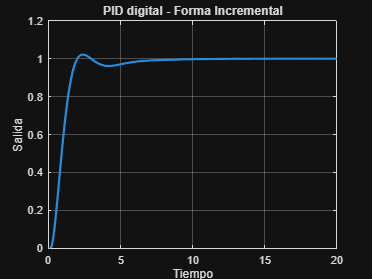

%% 3.2.2 PID DIGITAL - FORMA INCREMENTAL

y_inc = zeros(1,N); % salida
u_inc = zeros(1,N); % control
e_inc = zeros(1,N); % error

x = zeros(size(A,1),1);

for k = 3:N
    
    % calcular error
    e_inc(k) = r(k) - y_inc(k-1);
    
    % incremento del control
    du = Kp9*(e_inc(k)-e_inc(k-1)) ...
       + Ki9*Ts*e_inc(k) ...
       + Kd9/Ts*(e_inc(k)-2*e_inc(k-1)+e_inc(k-2));
    
    % actualizar señal de control
    u_inc(k) = u_inc(k-1) + du;
    
    % evolucion de la planta
    x = x + Ts*(A*x + B*u_inc(k));
    
    y_inc(k) = C*x;
    
end

figure
plot(td,y_inc,'LineWidth',2)
grid on
title('PID digital - Forma Incremental')
xlabel('Tiempo')
ylabel('Salida')

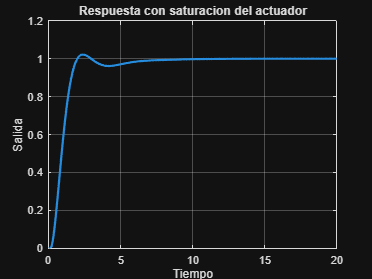

%% 3.3 SATURACION DEL ACTUADOR

umin = -5; % limite inferior
umax = 5;  % limite superior

y_sat = zeros(1,N);
u_sat = zeros(1,N);
e_sat = zeros(1,N);

x = zeros(size(A,1),1);

for k = 3:N
    
    e_sat(k) = r(k) - y_sat(k-1);
    
    du = Kp9*(e_sat(k)-e_sat(k-1)) ...
        + Ki9*Ts*e_sat(k) ...
        + Kd9/Ts*(e_sat(k)-2*e_sat(k-1)+e_sat(k-2));
    
    u_sat(k) = u_sat(k-1) + du;
    
    % aplicar saturacion
    u_sat(k) = max(min(u_sat(k),umax),umin);
    
    x = x + Ts*(A*x + B*u_sat(k));
    
    y_sat(k) = C*x;
    
end

figure
plot(td,y_sat,'LineWidth',2)
grid on
title('Respuesta con saturacion del actuador')
xlabel('Tiempo')
ylabel('Salida')

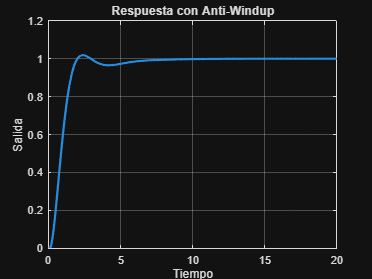

%% 3.4 ANTI-WINDUP POR RETROCALCULO

Tt = 0.2; % parametro de anti-windup

y_aw = zeros(1,N);
u_aw = zeros(1,N);
e_aw = zeros(1,N);

I = 0; % estado del integrador

x = zeros(size(A,1),1);

for k = 2:N
    
    e_aw(k) = r(k) - y_aw(k-1);
    
    P = Kp9*e_aw(k);
    
    D = Kd9*(e_aw(k)-e_aw(k-1))/Ts;
    
    u_unsat = P + I + D; % control antes de saturacion
    
    u_aw(k) = max(min(u_unsat,umax),umin); % control saturado
    
    % correccion anti-windup
    I = I + Ki9*Ts*e_aw(k) + (u_aw(k)-u_unsat)*Ts/Tt;
    
    x = x + Ts*(A*x + B*u_aw(k));
    
    y_aw(k) = C*x;
    
end

figure
plot(td,y_aw,'LineWidth',2)
grid on
title('Respuesta con Anti-Windup')
xlabel('Tiempo')
ylabel('Salida')

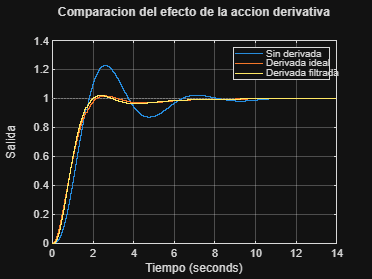

%% 3.5 EVALUACION DE LA ACCION DERIVATIVA

% Discretizar la planta para trabajar con el controlador digital
Gd = c2d(G,Ts,'zoh');

%CASO 1: SIN DERIVADA 

C_noD = pid(Kp9,Ki9,0);        % PID sin derivada
C_noD_d = c2d(C_noD,Ts,'tustin'); % discretizar controlador

T_noD = feedback(C_noD_d*Gd,1); % lazo cerrado

%CASO 2: DERIVADA IDEAL

C_ideal = pid(Kp9,Ki9,Kd9);        % PID completo
C_ideal_d = c2d(C_ideal,Ts,'tustin');

T_ideal = feedback(C_ideal_d*Gd,1);

%CASO 3: DERIVADA FILTRADA 

Nf = 10; % parametro del filtro derivativo

C_filt = pid(Kp9,Ki9,Kd9,1/Nf); % derivada filtrada
C_filt_d = c2d(C_filt,Ts,'tustin');

T_filt = feedback(C_filt_d*Gd,1);

%COMPARACION DE RESPUESTAS

figure
step(T_noD,T_ideal,T_filt)
grid on

legend('Sin derivada','Derivada ideal','Derivada filtrada')
title('Comparacion del efecto de la accion derivativa')
xlabel('Tiempo')
ylabel('Salida')

%% ============================================
% PREGUNTA 1
% Comparacion Forma Posicional vs Incremental
% ============================================

% Error
e_pos_final = 1 - y_pos;
e_inc_final = 1 - y_inc;

% IAE
IAE_pos = trapz(td,abs(e_pos_final));
IAE_inc = trapz(td,abs(e_inc_final));

% ITSE
ITSE_pos = trapz(td,td.*(e_pos_final.^2));
ITSE_inc = trapz(td,td.*(e_inc_final.^2));

% Informacion dinamica
info_pos = stepinfo(y_pos,td);
info_inc = stepinfo(y_inc,td);

% Energia de control
Eu_pos = trapz(td,u_pos.^2);
Eu_inc = trapz(td,u_inc.^2);

fprintf('\n------ COMPARACION POSICIONAL VS INCREMENTAL ------\n')


------ COMPARACION POSICIONAL VS INCREMENTAL ------


fprintf('IAE Posicional = %.4f\n',IAE_pos)

IAE Posicional = 1.0431


fprintf('IAE Incremental = %.4f\n',IAE_inc)

IAE Incremental = 1.0931



fprintf('ITSE Posicional = %.4f\n',ITSE_pos)

ITSE Posicional = 0.2822


fprintf('ITSE Incremental = %.4f\n',ITSE_inc)

ITSE Incremental = 0.3165



fprintf('Mp Posicional = %.2f %%\n',info_pos.Overshoot)

Mp Posicional = 2.11 %


fprintf('Mp Incremental = %.2f %%\n',info_inc.Overshoot)

Mp Incremental = 2.11 %



fprintf('ts Posicional = %.4f s\n',info_pos.SettlingTime)

ts Posicional = 5.6519 s


fprintf('ts Incremental = %.4f s\n',info_inc.SettlingTime)

ts Incremental = 5.7018 s



fprintf('Energia Posicional = %.4f\n',Eu_pos)

Energia Posicional = 1.1542


fprintf('Energia Incremental = %.4f\n',Eu_inc)

Energia Incremental = 1.1528


%% ============================================
% PREGUNTA 2
% Evaluacion del parametro Tt (Anti-Windup)
% ============================================

Tt_values = [0.05 0.1 0.2 0.5 1];

IAE_Tt = zeros(size(Tt_values));
Eu_Tt = zeros(size(Tt_values));

for i = 1:length(Tt_values)

    Tt = Tt_values(i);

    y_temp = zeros(1,N);
    u_temp = zeros(1,N);
    e_temp = zeros(1,N);

    I = 0;
    x = zeros(size(A,1),1);

    for k = 2:N

        e_temp(k) = r(k) - y_temp(k-1);

        P = Kp9*e_temp(k);
        D = Kd9*(e_temp(k)-e_temp(k-1))/Ts;

        u_unsat = P + I + D;

        u_temp(k) = max(min(u_unsat,umax),umin);

        I = I + Ki9*Ts*e_temp(k) + (u_temp(k)-u_unsat)*Ts/Tt;

        x = x + Ts*(A*x + B*u_temp(k));

        y_temp(k) = C*x;

    end

    e_calc = 1 - y_temp;

    IAE_Tt(i) = trapz(td,abs(e_calc));
    Eu_Tt(i) = trapz(td,u_temp.^2);

end

Tabla_Tt = table(Tt_values',IAE_Tt',Eu_Tt',...
    'VariableNames',{'Tt','IAE','Energia_control'});

disp('Tabla comparativa de Tt:')

Tabla comparativa de Tt:


disp(Tabla_Tt)

     Tt      IAE      Energia_control
    ____    ______    _______________

    0.05    1.0386        1.1499     
     0.1    1.0386        1.1499     
     0.2    1.0386        1.1499     
     0.5    1.0386        1.1499     
       1    1.0386        1.1499     



%% ============================================
% PREGUNTA 3
% Evaluacion del efecto de la accion derivativa
% ============================================

[y_noD,t_noD] = step(T_noD,20);
[y_ideal,t_ideal] = step(T_ideal,20);
[y_filt,t_filt] = step(T_filt,20);

% Errores
e_noD = 1 - y_noD;
e_ideal = 1 - y_ideal;
e_filt = 1 - y_filt;

% IAE
IAE_noD = trapz(t_noD,abs(e_noD));
IAE_ideal = trapz(t_ideal,abs(e_ideal));
IAE_filt = trapz(t_filt,abs(e_filt));

% Informacion dinamica
info_noD = stepinfo(y_noD,t_noD);
info_ideal = stepinfo(y_ideal,t_ideal);
info_filt = stepinfo(y_filt,t_filt);

fprintf('EFECTO DE LA DERIVADA ')

EFECTO DE LA DERIVADA 


fprintf('IAE sin derivada = %.4f\n',IAE_noD)

IAE sin derivada = 1.6296


fprintf('IAE derivada ideal = %.4f\n',IAE_ideal)

IAE derivada ideal = 1.0405


fprintf('IAE derivada filtrada = %.4f\n',IAE_filt)

IAE derivada filtrada = 1.0402



fprintf('Mp sin derivada = %.2f %%\n',info_noD.Overshoot)

Mp sin derivada = 22.69 %


fprintf('Mp derivada ideal = %.2f %%\n',info_ideal.Overshoot)

Mp derivada ideal = 1.70 %


fprintf('Mp derivada filtrada = %.2f %%\n',info_filt.Overshoot)

Mp derivada filtrada = 1.93 %



fprintf('ts sin derivada = %.4f s\n',info_noD.SettlingTime)

ts sin derivada = 7.3889 s


fprintf('ts derivada ideal = %.4f s\n',info_ideal.SettlingTime)

ts derivada ideal = 5.7625 s


fprintf('ts derivada filtrada = %.4f s\n',info_filt.SettlingTime)

ts derivada filtrada = 5.5001 s


**PROBLEMA 2. Planta contextualizada con unidades y restricciones**

clear; clc; close all
clear tf

s = tf('s');


MODELO DE LA PLANTA (variables de desviacion)


K  = 10;
T1 = 0.6;    % constante dominante
T2 = 0.12;
T3 = 0.04;
L  = 0.15;   % retardo

den = conv(conv([T1 1],[T2 1]),[T3 1]);
G   = tf(K, den);
G.InputDelay = L;

% Cambio de referencia en variables de desviacion
ref = 20;    % Dy* = +20 rad/s

t = 0:0.001:5;

PUNTO 1 - CURVA DE REACCION Y MODELO FOPDT


[y,t1] = step(G, t);

figure('Name','Curva de reaccion')
plot(t1, y, 'LineWidth', 2)
grid on
title('Respuesta al escalon de la planta \Delta G(s)')
xlabel('Tiempo [s]')
ylabel('\Delta y [rad/s]')


% Aproximacion FOPDT: T_approx = T1+T2, L_approx = T3+L 
% Justificacion: metodo de sumas de constantes de tiempo para sistemas
% de orden superior. La constante dominante absorbe las menores.
T_fopdt = T1 + T2;     % = 0.72 s
L_fopdt = T3 + L;      % = 0.19 s

Gf = tf(K, [T_fopdt 1]);
Gf.InputDelay = L_fopdt;

[yf, tfop] = step(Gf, t);

figure('Name','Comparacion FOPDT')
plot(t1,  y,  'LineWidth', 2)
hold on
plot(tfop, yf, '--', 'LineWidth', 2)
legend('Planta real G(s)','Modelo FOPDT')
title('Aproximacion FOPDT para sintonizacion')
xlabel('Tiempo [s]'), ylabel('\Delta y [rad/s]')
grid on


fprintf(' MODELO FOPDT ')

 MODELO FOPDT 

fprintf('K      = %.3f\n', K)

K      = 10.000


fprintf('T_fopdt= %.3f s\n', T_fopdt)

T_fopdt= 0.720 s


fprintf('L_fopdt= %.3f s\n', L_fopdt)

L_fopdt= 0.190 s


fprintf('Relacion L/T = %.3f  (proceso con retardo moderado)\n', L_fopdt/T_fopdt)

Relacion L/T = 0.264  (proceso con retardo moderado)


PUNTO 1b - DETERMINACION Ku y Pu (oscilacion sostenida)


[Kgm, Pm, Wcg, ~] = margin(G);


Ku = Kgm;
Pu = 2*pi / Wcg;

fprintf('PARAMETROS DE OSCILACION SOSTENIDA')

PARAMETROS DE OSCILACION SOSTENIDA

fprintf('Ku = %.4f\n', Ku)

Ku = 0.5019


fprintf('Pu = %.4f s\n', Pu)

Pu = 1.0026 s



Cku  = pid(Ku, 0, 0);
Tku  = feedback(Cku*G, 1);
[yku, tku] = step(ref*Tku, 0:0.001:10);

figure('Name','Oscilacion sostenida Ku')
plot(tku, yku, 'LineWidth', 2)
grid on
title(sprintf('Oscilacion sostenida  Ku=%.3f', Ku))
xlabel('Tiempo [s]'), ylabel('\Delta y [rad/s]')

PUNTO 2 - DISENO PID CONTINUO (dos metodos)



%% --- METODO 1: Ziegler-Nichols 
Kp_ZN = 1.2  * T_fopdt / (K * L_fopdt);
Ti_ZN = 2    * L_fopdt;
Td_ZN = 0.5  * L_fopdt;

Ki_ZN = Kp_ZN / Ti_ZN;
Kd_ZN = Kp_ZN * Td_ZN;

%% METODO 2: CHR Servo 20% sobreimpulso
Kp_CHR = 0.95 * T_fopdt / (K * L_fopdt);
Ti_CHR = 1.357 * T_fopdt;
Td_CHR = 0.473 * L_fopdt;

Ki_CHR = Kp_CHR / Ti_CHR;
Kd_CHR = Kp_CHR * Td_CHR;

C_ZN  = pid(Kp_ZN,  Ki_ZN,  Kd_ZN);
C_CHR = pid(Kp_CHR, Ki_CHR, Kd_CHR);

Tzn  = feedback(C_ZN  * G, 1);
Tchr = feedback(C_CHR * G, 1);

[yzn,  t2] = step(ref*Tzn,  t);
[ychr, t3] = step(ref*Tchr, t);

figure('Name','Comparacion ZN vs CHR')
plot(t2, yzn,  'LineWidth', 2), hold on
plot(t3, ychr, 'LineWidth', 2)
yline(ref, '--k', 'Referencia')
legend('Ziegler-Nichols','CHR Servo 20%')
title('Comparacion metodos de sintonizacion (continuo)')
xlabel('Tiempo [s]'), ylabel('\Delta y [rad/s]')
grid on


info_ZN  = stepinfo(yzn,  t2, ref);
info_CHR = stepinfo(ychr, t3, ref);

IAE_ZN  = trapz(t2, abs(ref - yzn));
IAE_CHR = trapz(t3, abs(ref - ychr));
ITSE_ZN  = trapz(t2, t2(:) .* (ref - yzn).^2);
ITSE_CHR = trapz(t3, t3(:) .* (ref - ychr).^2);

tabla_metodos = table( ...
    [info_ZN.Overshoot;  info_CHR.Overshoot], ...
    [info_ZN.SettlingTime; info_CHR.SettlingTime], ...
    [IAE_ZN;  IAE_CHR], ...
    [ITSE_ZN; ITSE_CHR], ...
    'VariableNames', {'Overshoot_pct','Ts_seg','IAE','ITSE'}, ...
    'RowNames',      {'ZieglerNichols','CHR_20pct'});

disp(' ')

disp('TABLA COMPARATIVA METODOS CONTINUOS ')

TABLA COMPARATIVA METODOS CONTINUOS 


disp(tabla_metodos)

                      Overshoot_pct    Ts_seg     IAE       ITSE 
                      _____________    ______    ______    ______

    ZieglerNichols       91.704           NaN    21.608    148.31
    CHR_20pct             36.27        2.2148    10.021    26.351




% Criterio de seleccion: CHR como punto de partida para optimizacion
% ZN tipicamente produce Mp>>10%, CHR parte mas cerca de las specs



PUNTO 2b - OPTIMIZACION DEL PID FINAL

fun = @(x) costPID(x, G, ref);

% Punto inicial: CHR 
x0 = [Kp_CHR, Ki_CHR, Kd_CHR];

options = optimset('MaxIter', 5000, 'TolX', 1e-8, 'TolFun', 1e-8, ...
                   'Display', 'iter');

x_opt = fminsearch(fun, x0, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1           147326         
     1            4           138348         initial simplex
     2            6          71109.1         expand
     3            7          71109.1         reflect
     4            9            25035         expand
     5           11          4953.23         expand
     6           12          4953.23         reflect
     7           13          4953.23         reflect
     8           15          4531.26         contract inside
     9           17          4531.26         contract inside
    10           19          4531.26         contract inside
    11           20          4531.26         reflect
    12           22          3549.22         reflect
    13           24           3340.1         expand
    14           26           3340.1         contract inside
    15           28          2751.97         expand
    16           30          1442.84         reflect
    17        


Kp = abs(x_opt(1));
Ki = abs(x_opt(2));
Kd = abs(x_opt(3));

C_final = pid(Kp, Ki, Kd);

fprintf('CONTROLADOR PID FINAL OPTIMIZADO ')

CONTROLADOR PID FINAL OPTIMIZADO 

fprintf('Kp = %.4f\n', Kp)

Kp = 0.2271


fprintf('Ki = %.4f\n', Ki)

Ki = 0.3259


fprintf('Kd = %.4f\n', Kd)

Kd = 0.0348


fprintf('Ti = Kp/Ki = %.4f s\n', Kp/Ki)

Ti = Kp/Ki = 0.6970 s


fprintf('Td = Kd/Kp = %.4f s\n', Kd/Kp)

Td = Kd/Kp = 0.1531 s



Tfinal = feedback(C_final * G, 1);

[yopt, t4] = step(ref*Tfinal, t);

figure('Name','Respuesta PID optimizado')
plot(t4, yopt, 'b', 'LineWidth', 2), hold on
yline(ref, '--r', 'Referencia')
grid on
title('Respuesta sistema con PID optimizado (continuo)')
xlabel('Tiempo [s]'), ylabel('\Delta y [rad/s]')


info_final = stepinfo(yopt, t4, ref);
fprintf(' Verificacion de especificaciones')

 Verificacion de especificaciones

fprintf('Mp  = %.3f %%  (especificacion: < 10 %%)\n',  info_final.Overshoot)

Mp  = 2.000 %  (especificacion: < 10 %)


fprintf('ts  = %.4f s  (especificacion: < 0.6 s)\n',   info_final.SettlingTime)

ts  = 0.5221 s  (especificacion: < 0.6 s)


if info_final.Overshoot < 10 && info_final.SettlingTime < 0.6
    fprintf('CUMPLE AMBAS ESPECIFICACIONES')
else
    fprintf('No cumple alguna especificacion')
end

CUMPLE AMBAS ESPECIFICACIONES


%% Tabla comparativa final (tres controladores) 
ess_ZN  = abs(ref - yzn(end));
ess_CHR = abs(ref - ychr(end));
ess_PID = abs(ref - yopt(end));

IAE_PID  = trapz(t4, abs(ref - yopt));
ITSE_PID = trapz(t4, t4(:) .* (ref - yopt).^2);

tabla_comparacion = table( ...
    [info_ZN.SettlingTime;  info_CHR.SettlingTime;  info_final.SettlingTime], ...
    [info_ZN.Overshoot;     info_CHR.Overshoot;     info_final.Overshoot], ...
    [IAE_ZN;  IAE_CHR;  IAE_PID], ...
    [ITSE_ZN; ITSE_CHR; ITSE_PID], ...
    [ess_ZN;  ess_CHR;  ess_PID], ...
    'VariableNames', {'Ts_seg','Overshoot_pct','IAE','ITSE','Error_estacionario'}, ...
    'RowNames',      {'ZieglerNichols','CHR_20pct','PID_Optimizado'});

disp(' ')

disp('COMPARACION FINAL DE CONTROLADORES')

COMPARACION FINAL DE CONTROLADORES


disp(tabla_comparacion)

                      Ts_seg     Overshoot_pct     IAE       ITSE     Error_estacionario
                      _______    _____________    ______    ______    __________________

    ZieglerNichols        NaN       91.704        21.608    148.31          0.42915     
    CHR_20pct          2.2148        36.27        10.021    26.351         0.013266     
    PID_Optimizado    0.52213            2         6.916    15.469        0.0001246     



ANALISIS EN FRECUENCIA - LAZO ABIERTO (Opcional)

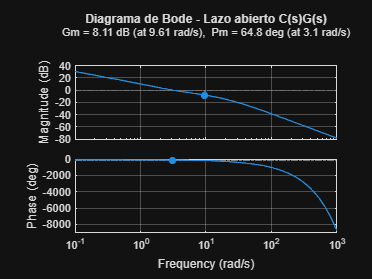


L_ol = C_final * G;    % funcion de lazo abierto C(s)*G(s)

[Gm_f, Pm_f, Wcg_f, Wcp_f] = margin(L_ol);

figure('Name','Bode lazo abierto')
margin(L_ol)
title('Diagrama de Bode - Lazo abierto C(s)G(s)')
grid on


fprintf(' MARGENES DE ESTABILIDAD (lazo abierto) ')

 MARGENES DE ESTABILIDAD (lazo abierto) 

fprintf('Margen de ganancia Gm = %.3f dB  (%.3f lineal)\n', 20*log10(Gm_f), Gm_f)

Margen de ganancia Gm = 8.107 dB  (2.543 lineal)


fprintf('Margen de fase     Pm = %.2f deg\n', Pm_f)

Margen de fase     Pm = 64.81 deg


fprintf('Frec. cruce ganancia Wcg = %.3f rad/s\n', Wcg_f)

Frec. cruce ganancia Wcg = 9.613 rad/s


fprintf('Frec. cruce fase    Wcp = %.3f rad/s\n', Wcp_f)

Frec. cruce fase    Wcp = 3.102 rad/s


PUNTO 3 - IMPLEMENTACION DIGITAL


Ts_d = 0.05;   % periodo de muestreo [s]

%% 3.1 Discretizacion Tustin -
Cd = c2d(C_final, Ts_d, 'tustin');

[numd, dend] = tfdata(Cd, 'v');

fprintf(' PID DISCRETIZADO (Tustin, Ts=%.2f s)', Ts_d)

 PID DISCRETIZADO (Tustin, Ts=0.05 s)

fprintf('Numerador:   '); fprintf('%.6f  ', numd); fprintf('\n')

Numerador:   1.625968  -2.765089  1.171710  


fprintf('Denominador: '); fprintf('%.6f  ', dend); fprintf('\n')

Denominador: 1.000000  0.000000  -1.000000  


Planta discreta para simulacion 

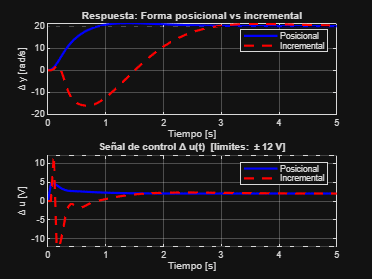

Gd = c2d(G, Ts_d, 'zoh');
[Ad, Bd, Cd2, Dd] = ssdata(ss(Gd));



t_sim   = (0:Ts_d:5)';
N       = length(t_sim);

% Limites en variables de desviacion
umin = -12;   % Du_min = 0  - u0 = 0  - 12 = -12 V
umax =  12;   % Du_max = 24 - u0 = 24 - 12 = +12 V

x_pos  = zeros(size(Ad,1), 1);
y_pos  = zeros(N, 1);
u_pos  = zeros(N, 1);
e_pos  = zeros(N, 1);
I_pos  = 0;
sat_cnt = 0;

Ti_aw = Kp / Ki;          % = Ti
Td_aw = Kd / Kp;          % = Td
Tt    = sqrt(Ti_aw * Td_aw);  % tiempo de retrocalculo recomendado

for k = 2:N
    e_pos(k) = ref - y_pos(k-1);

    P = Kp * e_pos(k);

    % Derivada en la salida (evita kick de derivada ante escalon)
    if k > 2
        dy = (y_pos(k-1) - y_pos(k-2)) / Ts_d;
    else
        dy = 0;
    end
    D = -Kd * dy;

    u_unsat = P + I_pos + D;

    % Saturacion fisica en variables de desviacion
    u_sat = min(max(u_unsat, umin), umax);

    if u_sat ~= u_unsat
        sat_cnt = sat_cnt + 1;
    end

    % Anti-windup por retrocalculo
    I_pos = I_pos + Ki * Ts_d * e_pos(k) + (u_sat - u_unsat) * Ts_d / Tt;

    u_pos(k) = u_sat;

    % Avanzar estado de la planta
    x_pos = Ad * x_pos + Bd * u_pos(k);
    y_pos(k) = Cd2 * x_pos;
end



x_inc  = zeros(size(Ad,1), 1);
y_inc  = zeros(N, 1);
u_inc  = zeros(N, 1);
e_inc  = zeros(N, 1);

% Coeficientes forma incremental (PID discreto Tustin)
% Se usan los coeficientes del PID continuo como aproximacion de Euler adelante
% para la forma incremental estandar:
q0 = Kp * (1 + Ts_d/(2*Ti_aw) + 2*Td_aw/Ts_d);
q1 = Kp * (-1 + Ts_d/(2*Ti_aw) - 4*Td_aw/Ts_d);   % nota: signo convencional
q2 = Kp * (2*Td_aw/Ts_d);

% Alternativa directa (mas clara):
%  Du_k = Du_{k-1} + q0*e_k + q1*e_{k-1} + q2*e_{k-2}
% con q0,q1,q2 segun Astrom & Wittenmark

for k = 3:N
    e_inc(k) = ref - y_inc(k-1);

    % Incremento de control
    delta_u = q0*e_inc(k) + q1*e_inc(k-1) + q2*e_inc(k-2);

    u_unsat_inc = u_inc(k-1) + delta_u;

    % Saturacion (forma incremental: se clampea la salida total)
    u_inc(k) = min(max(u_unsat_inc, umin), umax);

    % Avanzar planta
    x_inc = Ad * x_inc + Bd * u_inc(k);
    y_inc(k) = Cd2 * x_inc;
end

%% Graficas forma posicional vs incremental 
figure('Name','Posicional vs Incremental')
subplot(2,1,1)
plot(t_sim, y_pos, 'b', 'LineWidth', 2), hold on
plot(t_sim, y_inc, 'r--', 'LineWidth', 2)
yline(ref, '--k')
legend('Posicional','Incremental')
title('Respuesta: Forma posicional vs incremental')
xlabel('Tiempo [s]'), ylabel('\Delta y [rad/s]')
grid on

subplot(2,1,2)
plot(t_sim, u_pos, 'b', 'LineWidth', 2), hold on
plot(t_sim, u_inc, 'r--', 'LineWidth', 2)
yline(umax, '--k'), yline(umin, '--k')
legend('Posicional','Incremental')
title('Señal de control \Delta u(t)  [limites: \pm12 V]')
xlabel('Tiempo [s]'), ylabel('\Delta u [V]')
grid on

EFECTO DEL ANTI-WINDUP (solo forma posicional)

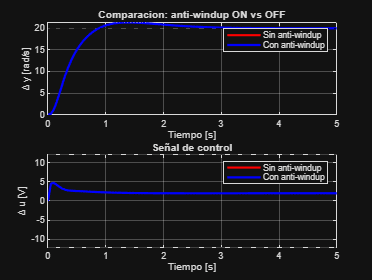


% --- SIN anti-windup ---
x_naw = zeros(size(Ad,1), 1);
y_naw = zeros(N, 1);
u_naw = zeros(N, 1);
I_naw = 0;

for k = 2:N
    e_naw = ref - y_naw(k-1);
    P_naw = Kp * e_naw;
    if k > 2
        D_naw = -Kd * (y_naw(k-1) - y_naw(k-2)) / Ts_d;
    else
        D_naw = 0;
    end
    u_unsat_naw = P_naw + I_naw + D_naw;
    u_sat_naw   = min(max(u_unsat_naw, umin), umax);
    % Sin anti-windup: integrador acumula aunque sature
    I_naw = I_naw + Ki * Ts_d * e_naw;
    u_naw(k) = u_sat_naw;
    x_naw = Ad * x_naw + Bd * u_naw(k);
    y_naw(k) = Cd2 * x_naw;
end

figure('Name','Efecto anti-windup')
subplot(2,1,1)
plot(t_sim, y_naw, 'r',  'LineWidth', 2), hold on
plot(t_sim, y_pos, 'b',  'LineWidth', 2)
yline(ref, '--k')
legend('Sin anti-windup','Con anti-windup')
title('Comparacion: anti-windup ON vs OFF')
xlabel('Tiempo [s]'), ylabel('\Delta y [rad/s]')
grid on

subplot(2,1,2)
plot(t_sim, u_naw, 'r', 'LineWidth', 2), hold on
plot(t_sim, u_pos, 'b', 'LineWidth', 2)
yline(umax, '--k'), yline(umin, '--k')
legend('Sin anti-windup','Con anti-windup')
title('Señal de control')
xlabel('Tiempo [s]'), ylabel('\Delta u [V]')
grid on

 EFECTO DERIVATIVO: sin / ideal / filtrada N=10

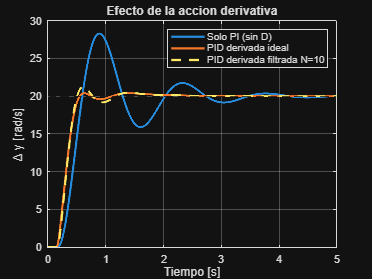


Nf = 10;
Tf_fil = Td_aw / Nf;    % constante de tiempo del filtro derivativo

% PID sin derivada
C_PI = pid(Kp, Ki, 0);
T_PI = feedback(C_PI*G, 1);

% PID derivada ideal (ya tenemos Tfinal)

% PID derivada filtrada
C_fil = pid(Kp, Ki, Kd, Tf_fil);
T_fil = feedback(C_fil*G, 1);

figure('Name','Efecto derivativo')
[y_pi,  tp]  = step(ref*T_PI,    t);
[y_id,  tid] = step(ref*Tfinal,  t);
[y_flt, tfl] = step(ref*T_fil,   t);

plot(tp,  y_pi,  'LineWidth', 2), hold on
plot(tid, y_id,  'LineWidth', 2)
plot(tfl, y_flt, '--', 'LineWidth', 2)
yline(ref, '--k')
legend('Solo PI (sin D)','PID derivada ideal','PID derivada filtrada N=10')
title('Efecto de la accion derivativa')
xlabel('Tiempo [s]'), ylabel('\Delta y [rad/s]')
grid on

 ANALISIS DE ROBUSTEZ: variacion ±20% en T1 (dominante)

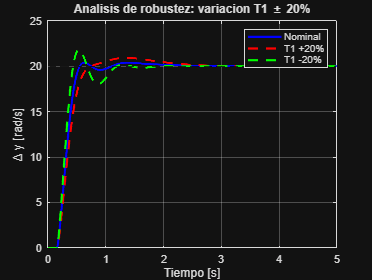


T1_mas  = 1.2 * T1;    % +20%
T1_men  = 0.8 * T1;    % -20%

den_mas = conv(conv([T1_mas 1],[T2 1]),[T3 1]);
den_men = conv(conv([T1_men 1],[T2 1]),[T3 1]);

Gv_mas = tf(K, den_mas); Gv_mas.InputDelay = L;
Gv_men = tf(K, den_men); Gv_men.InputDelay = L;

Trob_mas = feedback(C_final*Gv_mas, 1);
Trob_men = feedback(C_final*Gv_men, 1);

[y_nom, tn]  = step(ref*Tfinal,   t);
[y_mas, tma] = step(ref*Trob_mas, t);
[y_men, tme] = step(ref*Trob_men, t);

figure('Name','Robustez')
plot(tn,  y_nom, 'b',  'LineWidth', 2), hold on
plot(tma, y_mas, 'r--','LineWidth', 2)
plot(tme, y_men, 'g--','LineWidth', 2)
yline(ref, '--k')
legend('Nominal','T1 +20%','T1 -20%')
title('Analisis de robustez: variacion T1 \pm 20%')
xlabel('Tiempo [s]'), ylabel('\Delta y [rad/s]')
grid on


info_rob_mas = stepinfo(y_mas, tma, ref);
info_rob_men = stepinfo(y_men, tme, ref);

fprintf('ROBUSTEZ (T1 nominal=%.2f s)', T1)

ROBUSTEZ (T1 nominal=0.60 s)

fprintf('                 Mp [%%]   ts [s]\n')

                 Mp [%]   ts [s]


fprintf('Nominal:         %.2f     %.4f\n', info_final.SettlingTime, info_final.SettlingTime)

Nominal:         0.52     0.5221


fprintf('T1 +20%%:         %.2f     %.4f\n', info_rob_mas.Overshoot, info_rob_mas.SettlingTime)

T1 +20%:         4.65     2.0715


fprintf('T1 -20%%:         %.2f     %.4f\n', info_rob_men.Overshoot, info_rob_men.SettlingTime)

T1 -20%:         9.03     1.1147


 GRAFICAS COMPLETAS DE LA IMPLEMENTACION DIGITAL

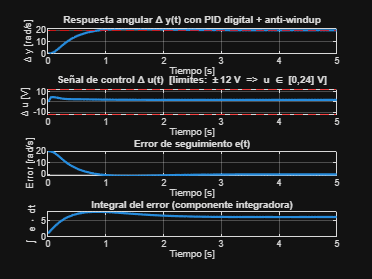


figure('Name','Implementacion digital completa')

subplot(4,1,1)
plot(t_sim, y_pos, 'LineWidth', 2), hold on
yline(ref, '--r')
title('Respuesta angular \Delta y(t) con PID digital + anti-windup')
xlabel('Tiempo [s]'), ylabel('\Delta y [rad/s]')
grid on

subplot(4,1,2)
plot(t_sim, u_pos, 'LineWidth', 2), hold on
yline(umax, '--r'), yline(umin, '--r')
title('Señal de control \Delta u(t)  [limites: \pm12 V  =>  u \in [0,24] V]')
xlabel('Tiempo [s]'), ylabel('\Delta u [V]')
grid on

subplot(4,1,3)
plot(t_sim, ref - y_pos, 'LineWidth', 2)
title('Error de seguimiento e(t)')
xlabel('Tiempo [s]'), ylabel('Error [rad/s]')
grid on

subplot(4,1,4)
plot(t_sim, cumsum(ref - y_pos)*Ts_d, 'LineWidth', 2)
title('Integral del error (componente integradora)')
xlabel('Tiempo [s]'), ylabel('\int e \cdot dt')
grid on

INDICADORES MINIMOS DE DESEMPEÑO


e_dig  = ref - y_pos;
t_col  = t_sim(:);
e_col  = e_dig(:);
u_col  = u_pos(:);

IAE_dig  = trapz(t_col, abs(e_col));
ITSE_dig = trapz(t_col, t_col .* (e_col.^2));
Eu_dig   = trapz(t_col, u_col.^2);
sat_pct  = 100 * sat_cnt / N;

info_dig = stepinfo(y_pos, t_sim, ref);

fprintf('INDICADORES DE DESEMPEÑO - IMPLEMENTACION DIGITAL')

INDICADORES DE DESEMPEÑO - IMPLEMENTACION DIGITAL

fprintf('IAE  (Integral Absolute Error)     = %.4f\n', IAE_dig)

IAE  (Integral Absolute Error)     = 8.8921


fprintf('ITSE (Integral Time Squared Error) = %.4f\n', ITSE_dig)

ITSE (Integral Time Squared Error) = 18.5626


fprintf('ts(2%%)                             = %.4f s\n', info_dig.SettlingTime)

ts(2%)                             = 2.4728 s


fprintf('Mp                                 = %.3f %%\n', info_dig.Overshoot)

Mp                                 = 6.624 %


fprintf('\nEnergia de control (Du^2)\n')


Energia de control (Du^2)


fprintf('Eu = %.4f V^2·s\n', Eu_dig)

Eu = 25.0815 V^2·s


fprintf('\nPorcentaje de tiempo en saturacion\n')


Porcentaje de tiempo en saturacion


fprintf('Saturacion = %.2f %%\n', sat_pct)

Saturacion = 0.00 %



fprintf('\nSanity check de variables absolutas:\n')


Sanity check de variables absolutas:


fprintf('u_max aplicado = %.3f V  => u_abs_max = %.3f V (limite: 24 V)\n', ...
    max(u_pos), max(u_pos)+12)

u_max aplicado = 4.668 V  => u_abs_max = 16.668 V (limite: 24 V)


fprintf('u_min aplicado = %.3f V  => u_abs_min = %.3f V (limite:  0 V)\n', ...
    min(u_pos), min(u_pos)+12)

u_min aplicado = 0.000 V  => u_abs_min = 12.000 V (limite:  0 V)


 FUNCION DE COSTO 


function J = costPID(x, G, ref)
    Kp = abs(x(1));
    Ki = abs(x(2));
    Kd = abs(x(3));

    % Proteccion: ganancias minimas
    if Kp < 1e-4 || Ki < 1e-4
        J = 1e6;
        return
    end

    C = pid(Kp, Ki, Kd);
    T = feedback(C*G, 1);

    t = 0:0.001:5;
    [y, t] = step(ref*T, t);

    if any(isnan(y)) || any(isinf(y))
        J = 1e6;
        return
    end

    info = stepinfo(y, t, ref);
    e    = ref - y;
    IAE  = trapz(t, abs(e));

    Mp = info.Overshoot;
    ts = info.SettlingTime;

    penalty = 0;

    if Mp > 10
        penalty = penalty + 200 * (Mp - 10)^2;  % penaliza solo exceso
    end

    if ts > 0.6
        penalty = penalty + 3000 * (ts - 0.6)^2;  % penaliza fuerte ts
    end

    if isnan(ts) || isnan(Mp)
        J = 1e6;
        return
    end

    % Pesos: IAE para precision, Mp moderado, ts mas pesado
    J = IAE + 10*Mp + 500*ts + penalty;
end